%close all
%clear
%clc

## test


%load("data_for_animation.mat");

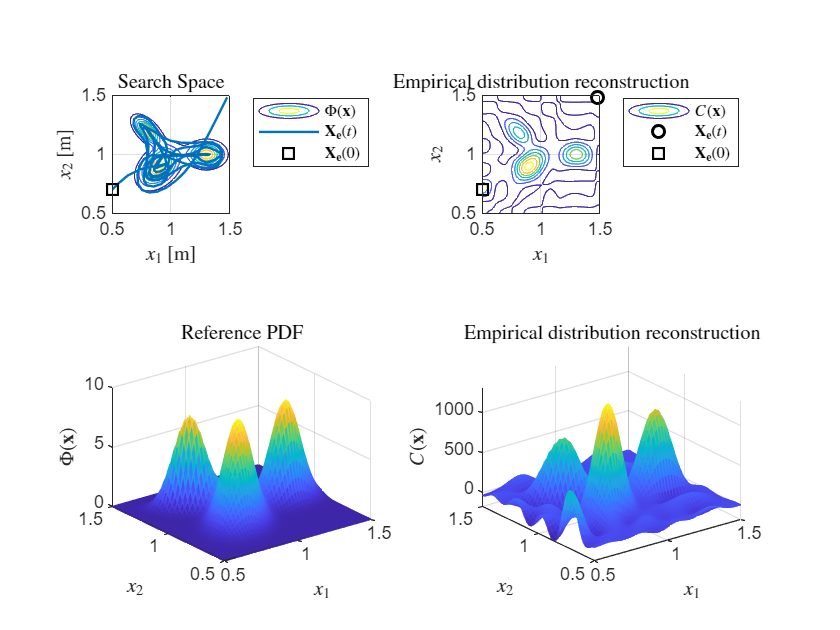


%Empirical distribution animation 2st Order system

figure(5)

for i = 1:length(t)

    subplot(2,2,1);
    contour(x_1_grid, x_2_grid, reshape(Phi_x, length(x_2), length(x_1)))
    xlim([L_1_l, L_1_u])
    ylim([L_2_l, L_2_u])
    title("Search Space",'Interpreter','latex')
    xlabel('$x_1$ [m]','Interpreter','latex')
    ylabel('$x_2$ [m]','Interpreter','latex')
    axis equal
    grid on
    hold on
    plot(X_e(:,1), X_e(:,2),'LineWidth',1.2)
    plot(X_e_0(1), X_e_0(2),'ksq','MarkerSize',7,'LineWidth',1.5)
    legend('$\Phi(\mathbf{x})$','$\mathbf{X_e}(t)$', '$\mathbf{X_e}(0)$',...
    'Interpreter','latex','Location','northeastoutside')
    hold off

    subplot(2,2,2);
    contour(x_1_grid, x_2_grid, reshape(C_x_reg(:,i), length(x_2), length(x_1)))
    xlim([L_1_l, L_1_u])
    ylim([L_2_l, L_2_u])
    title("Empirical distribution reconstruction",'Interpreter','latex')
    xlabel('$x_1$','Interpreter','latex')
    ylabel('$x_2$','Interpreter','latex')
    axis equal
    grid on
    hold on
    plot(X_e(i,1), X_e(i,2), 'ko', 'LineWidth', 1.5)
    plot(X_e_0(1), X_e_0(2),'ksq','MarkerSize',7,'LineWidth',1.5)
    legend('$C(\mathbf{x})$','$\mathbf{X_e}(t)$', '$\mathbf{X_e}(0)$',...
    'Interpreter','latex','Location','northeastoutside')
    hold off
    subplot(2,2,3);
    surf(x_1_grid, x_2_grid, reshape(Phi_x, length(x_2), length(x_1)),'EdgeColor','interp')
    xlim([L_1_l, L_1_u])
    ylim([L_2_l, L_2_u])
    title("Reference PDF",'Interpreter','latex')
    xlabel('$x_1$','Interpreter','latex')
    ylabel('$x_2$','Interpreter','latex')
    zlabel('$\Phi(\mathbf{x})$','Interpreter','latex')
    grid on
    subplot(2,2,4);
    surf(x_1_grid, x_2_grid, reshape(C_x_reg(:,i), length(x_2), length(x_1)),'EdgeColor','interp')
    xlim([L_1_l, L_1_u])
    ylim([L_2_l, L_2_u])
    title("Empirical distribution reconstruction",'Interpreter','latex')
    xlabel('$x_1$','Interpreter','latex')
    ylabel('$x_2$','Interpreter','latex')
    zlabel('$C(\mathbf{x})$','Interpreter','latex')
    grid on
    axis tight
    %shading flat
    colormap default

    drawnow limitrate

end